Script = "ManOnTheMoon.mlx";
mkdir("tmp")
export(Script,"tmp"+filesep+extractBefore(Script,"lx"));
mkdir("tmp"+filesep+"function")
cd("tmp")

code = splitlines(string(fileread("ManOnTheMoon.m")));
code = strtrim(code);
code(startsWith(code,"%")) = [];
ifunc = find(startsWith(code,"function"));
nfunc = length(ifunc);
ifunc = [ifunc; length(code)];
for i = 1:nfunc
    f = code(ifunc(i):ifunc(i+1)-1);
    if contains(f(1), "=")
        filename = "function"+filesep+strtrim(extractBetween(f(1),"=","("))+".m";
    elseif contains(f(1), "(")
        filename = "function"+filesep+strtrim(extractBetween(f(1),"function","("))+".m";
    else
        filename = "function"+filesep+strtrim(extractAfter(f(1),"function"))+".m";
    end
    fid = fopen(filename,'w');
    for l = 1:length(f)
        fprintf(fid,"%s\n",f(l));
    end
    fclose(fid);
end

code = code(1:ifunc(1)-1);
num = length(find(contains(code,"...")));

for n = 1:num
    i = find(contains(code,"..."),1,"last");
    code(i) = extractBefore(code(i),"...")+code(i+1);
    code(i+1) = [];
end

fid = fopen("test.m","w");
for l = 1:length(code)
    fprintf(fid,"%s",code(l));
    
    if (code(l) ~= "") & ~contains(code(l),string(iskeyword))
        if ~endsWith(code(l),";")
            fprintf(fid,";");
        end
%         fprintf(fid,"disp('"+code(l)+"');");
        fprintf(fid,"whos;");
        % Add disp "CODE"
        % Add disp whos
    end

    fprintf(fid,"\n");
end
fclose(fid);

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



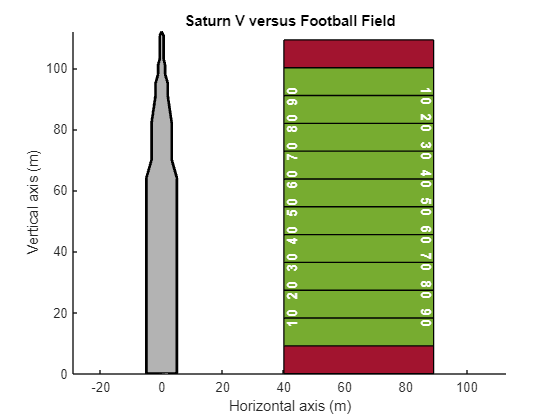

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



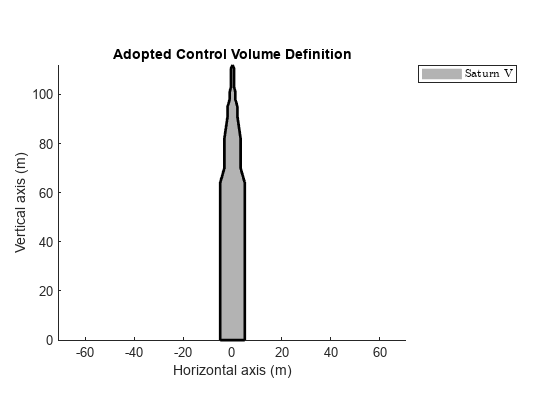

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



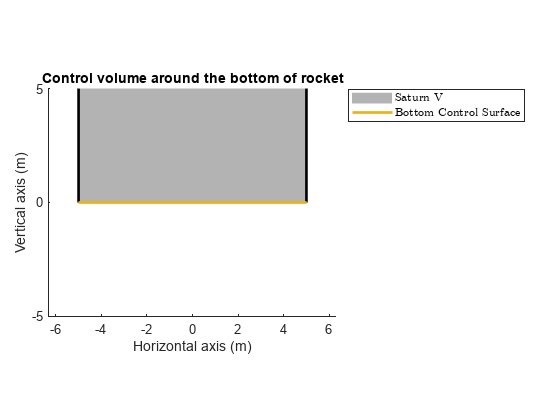

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              



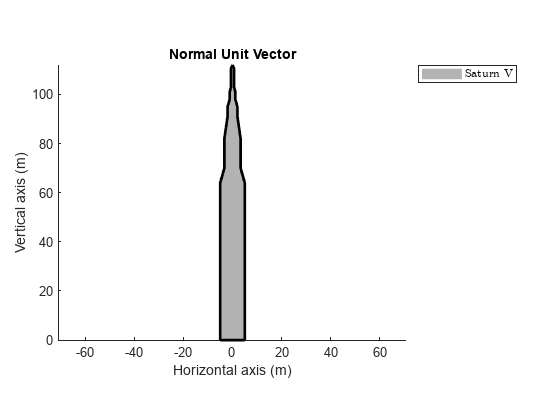

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1 

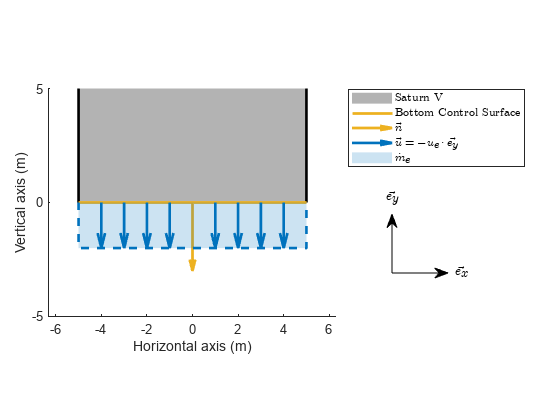

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



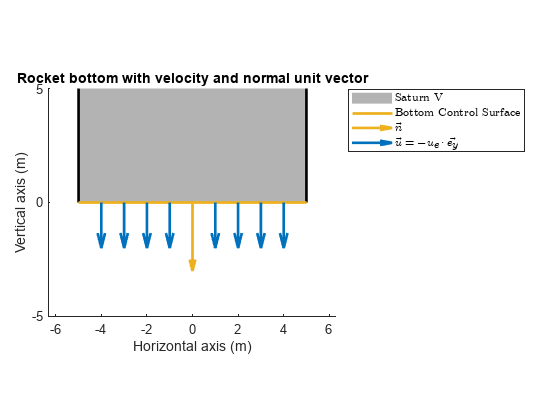

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       



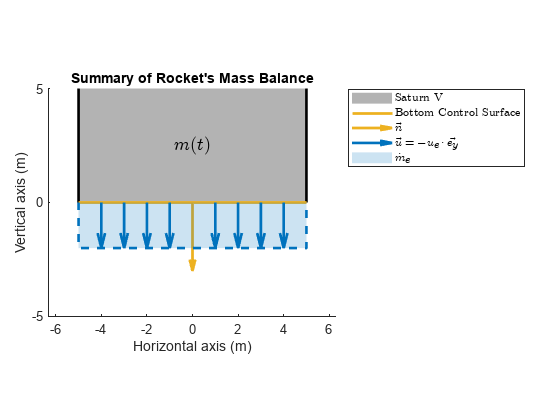

  Name      Size            Bytes  Class                        Attributes

  ans       1x1                 8  matlab.graphics.axis.Axes              
  f         1x1                 8  matlab.ui.Figure                       

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



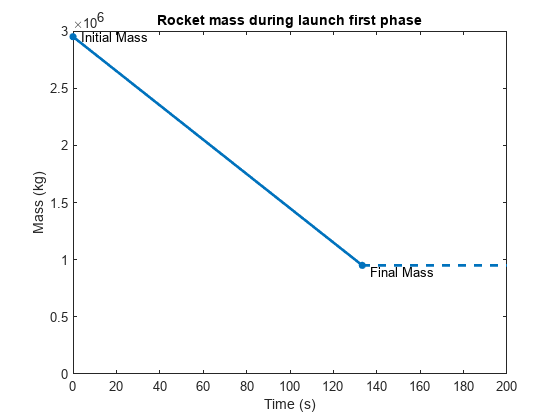

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



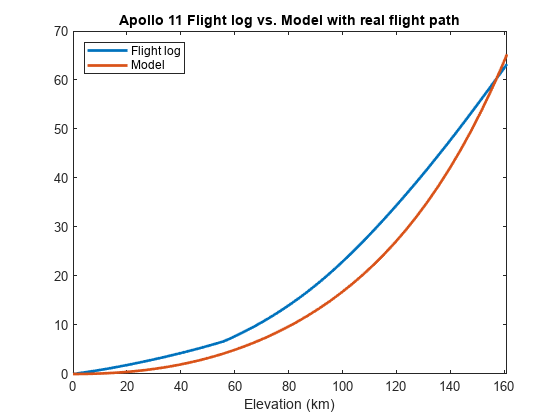

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



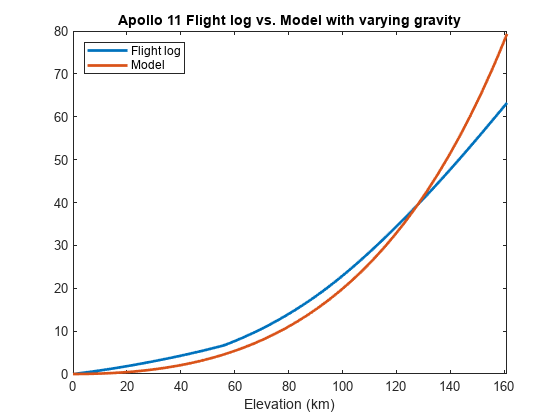

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



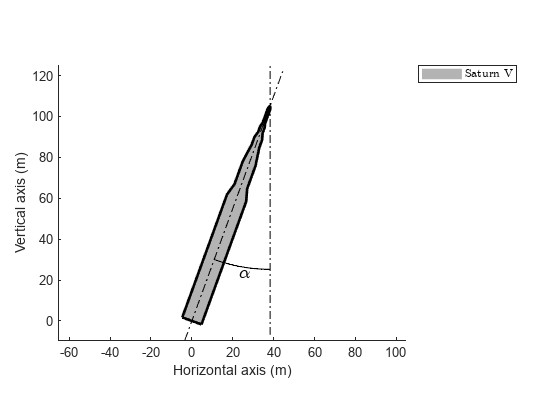

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



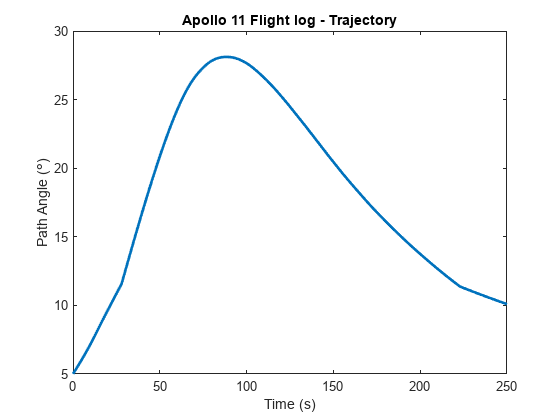

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



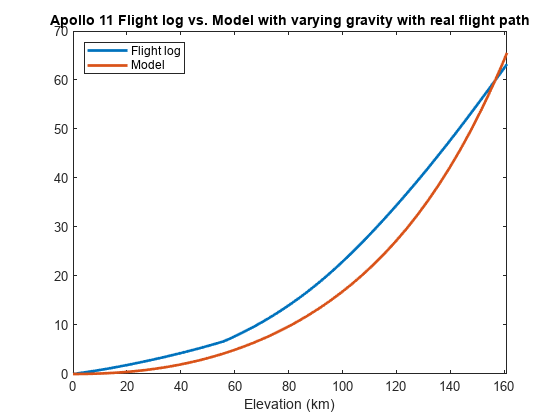

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       

  Name          Size            Bytes  Class                        Attributes

  MassFlow      1x1                 8  double                                 
  RP            1x1                 1  logical                                
  ans           1x1                 8  matlab.graphics.axis.Axes              
  f             1x1                 8  matlab.ui.Figure                       



clear
diary test.txt
diary on
run("test.m");

diary off